[x, y] = meshgrid(-3:0.1:1, -3:0.1:1);
f = x.*y - x.^2 - y.^2 - 2*x - 2*y + 4;

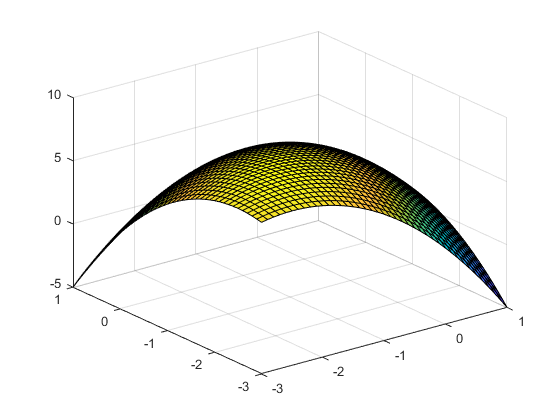

clf
surf(x, y, f)

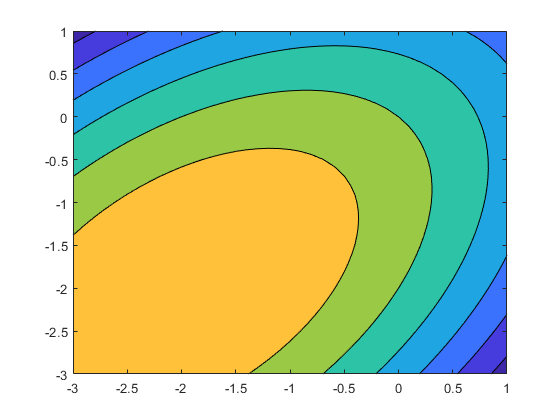

clf
contourf(x, y, f)

[px, py] = gradient(f, 0.1, 0.1);

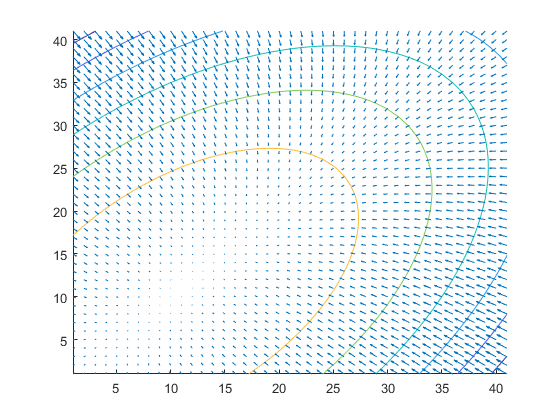

clf
hold on
contour(f)
quiver(px, py)

r0x = 1;
r0y = -1;
lambda0 = 0.1;

grad = [r0y - 2*r0x - 2; r0x - 2*r0y - 2]

grad =     -5
     1


r1 = grad * lambda0;

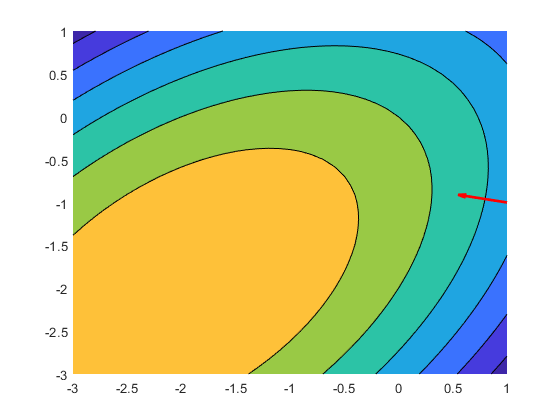

clf
hold on
contourf(x, y, f)
quiver(r0x, r0y, r1(1), r1(2), 'r', "LineWidth", 2, "MaxHeadSize", 0.5)

ang = atan2(grad(1), grad(2))

ang = -1.3734

r1_norm = norm(r1)

r1_norm = 0.5099

r1x = r0x + r1(1);
r1y = r0y + r1(2);

grad = [r1y - 2*r1x - 2; r1x - 2*r1y - 2]

grad =    -3.9000
    0.3000


sigma = 0.9

sigma = 0.9000

lambda1 = lambda0 * sigma

lambda1 = 0.0900

r2 = lambda1 * grad;

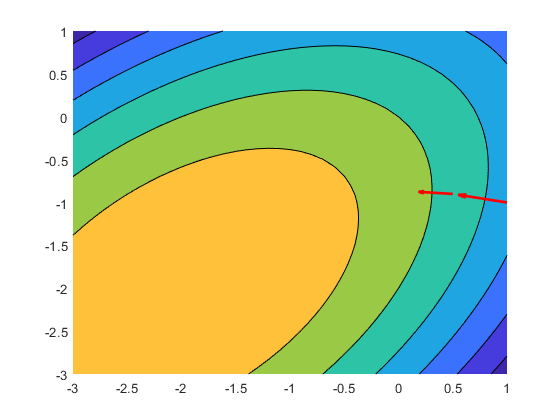

clf
hold on
contourf(x, y, f)
quiver(r0x, r0y, r1(1), r1(2), 'r', "LineWidth", 2, "MaxHeadSize", 0.5)
quiver(r1x, r1y, r2(1), r2(2), 'r', "LineWidth", 2, "MaxHeadSize", 0.5)